# **wavelet-RnB Live, version 02**

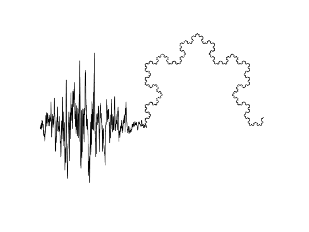

## *Wavelet-RnB ( Fig.2 ) *

#### *(J.M. Lina, M-C. Foti, 2024)*

#### The main reference: J. Dubé et al., *Rhythms and Background (RnB): the spectroscopy of sleep recordings*, 2024

The following sections should be executed in order

- 1) **NEURAL MASS** (with a little amount of scale free background) 

 
clc; clear; close all;
addpath('./ressources');
addpath(genpath('./RnB_v01/'));
addpath('./data/');
load('ChatGPTSimulator_1overf.mat','signal','time','fs','exponent');
load('JansRit.mat','neural_mass');
r = 0.04;
data = r*signal + neural_mass;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fprintf('  - This section applies w-RnB to a single\n')%
fprintf('    time series (a neural mass response)\n')  %
% Calculs:                                             %
OPTIONS.schrinkage = 1;                                %
OPTIONS.fractional = 1;                                %
OPTIONS.J      = 9;                                    %
OPTIONS.jnoise = 1;                                    %
OPTIONS.alpha0 = 4;                                    %
OPTIONS.beta   = [];                                   %
% w-RnB:                                               %
[sR0, ~] = wRnB_extract_Rhythmic_signals(data,OPTIONS);%
% Spectral density of the rhythmic response:           %
W0       = RnB_compute_spectre_brut(sR0,fs);           %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
f1 = make_fig1(time,data,W0);

- 2) **NEURAL MASS + scale free background**

- a) Realistic simulation (example with beta parameter = 2.2) 

- b) Standard Fourier analysis: power spectrum

- c) w-RnB rhythmic signal from the previous realistic simulation

- d) w-RnB spectroscopy: Fourier analysis of the previous rhythmic w-RnB signal

 
r = 0.04;
data = signal + r * neural_mass;
fprintf('  - This section defines a single time series\n');
fprintf('    (a neural mass response with an arrhythmic\n')
fprintf('    background).\n')
f2 = make_fig2(time,data,exponent);

 
fprintf('  - This section estimates the Hurst exponent from\n');
fprintf('    the resampling of the spectrum (IRASA approach)\n')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
W  = RnB_compute_spectre_brut(data,fs);         %
param.nresamp = 60;                             %
param.frange  = [2 45];                         %
[P,R]  = RnB_clean_spectrum_1of(data,fs,param); %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
f3 = make_fig3(P,W,R);

 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculs:                                              %
OPTIONS.schrinkage = 1;                                 %
OPTIONS.fractional = 1;                                 %
OPTIONS.J      = 9;                                     %
OPTIONS.jnoise = 1;                                     %
OPTIONS.alpha0 = 4;                                     %
OPTIONS.beta   = [];                                    %
[sR1,pW1] = wRnB_extract_Rhythmic_signals(data,OPTIONS);%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
f4 = make_fig4(time,sR1);

 
WR1 = RnB_compute_spectre_brut(sR1,fs);
f5 = make_fig5(WR1,pW1);
